1번 문제

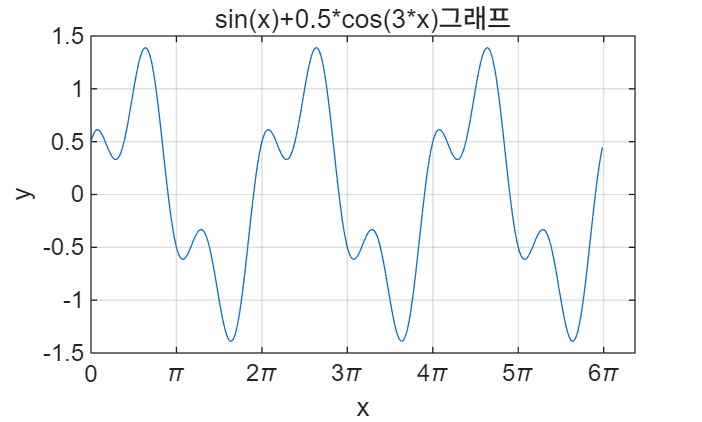

clear;
clc;

x=0:0.05:6*(pi);
y=sin(x)+0.5*cos(3*x);
plot(x,y);

xticks(0:(pi):6*(pi));
xticklabels({'0','\pi','2\pi','3\pi','4\pi','5\pi','6\pi'});
title('sin(x)+0.5*cos(3*x)그래프');
xlabel('x');
ylabel('y');
grid on

2번 문제

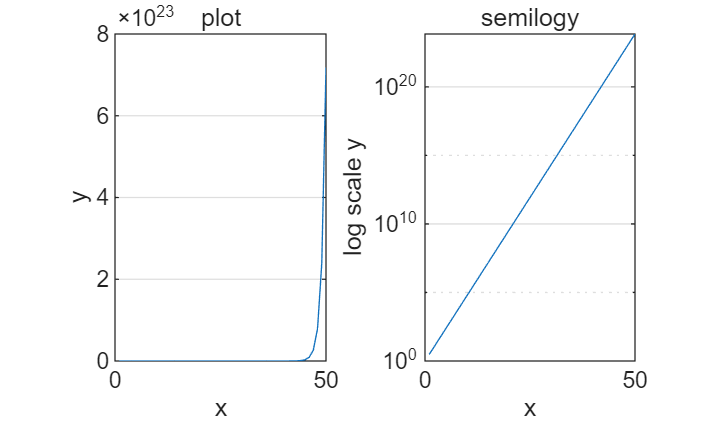

clear;
clc;

x=1:1:50;
y=3.^x;

figure;

subplot(1,2,1);
plot(x,y);

title('plot');
xlabel('x');
ylabel('y');
grid on;

subplot(1,2,2);
semilogy(x,y);

title('semilogy');
xlabel('x');
ylabel('log scale y');
grid on; 


%두 그래프의 차이 plot의 경우 x의 값이 증가할 때 y 값은 초반에는 작게 증가하다 나중에 급격하게 증가함. semilogy의
%경우 그래프가 직선 형태로 표현됨.

3번 문제

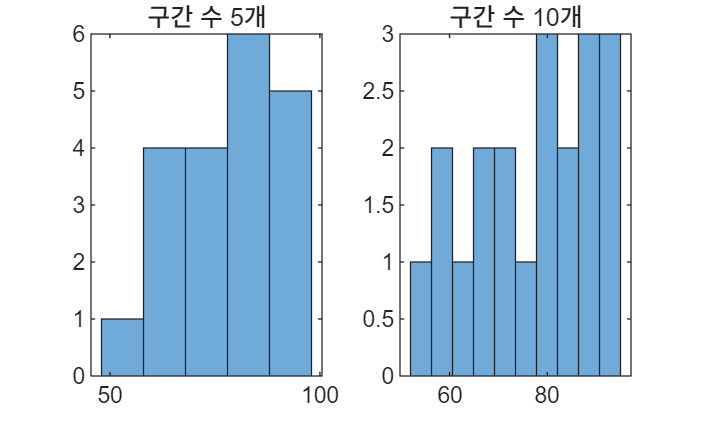

clear;
clc;

score=[72,85,91,66,78,88,95,54,60,73,82,90,69,77,84,92,58,63,79,87];

save('score.dat','score','-ascii');
data=load('score.dat');

figure;

subplot(1,2,1);
histogram(data,5);
title('구간 수 5개');

subplot(1,2,2);
histogram(data,10);
title('구간 수 10개');

4번 문제

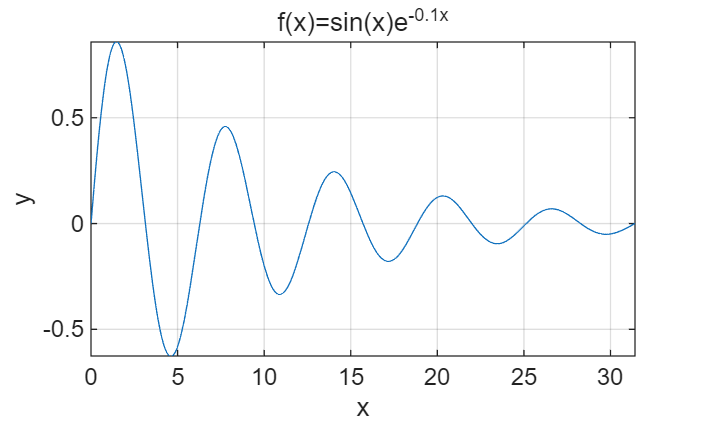

clear;
clc;

f=@(x) sin(x).*exp(-0.1*x);

figure;

fplot(f,[0,10*pi]);

title('f(x)=sin(x)e^{-0.1x}');
xlabel('x');
ylabel('y');
grid on;

5번 문제

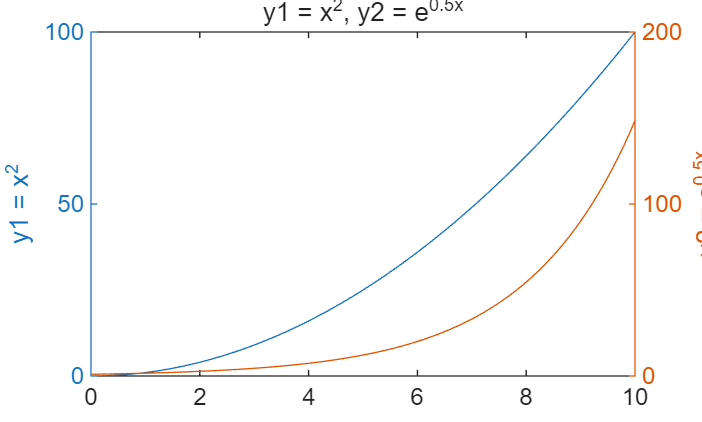

clear;
clc;

x=0:0.1:10;

y1=x.^2;
y2=exp(0.5*x);

figure;

[ax,Line1,Line2]=plotyy(x, y1, x, y2);

title('y1 = x^2, y2 = e^{0.5x}');
xlabel('x');

ylabel(ax(1),'y1 = x^2');    
ylabel(ax(2),'y2 = e^{0.5x}');


%증가 양상: y1은 x의 값이 증가할수록 y의 값은 계속 갈수록 커지고 y2는 x값이 증가할수록 y의 값은 초반에는 작게 증가하다 나중에는 점점 커짐.

6번 문제

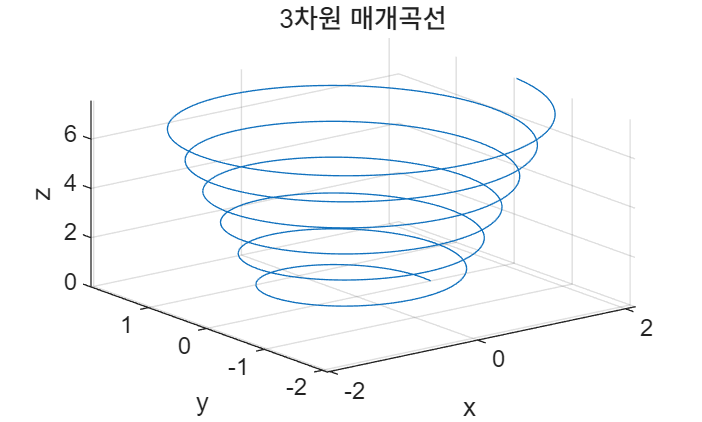

clear;
clc;

t=0:0.02:12*pi;

x=(1+0.03*t).*cos(t);
y=(1+0.03*t).*sin(t);
z=0.2*t;

figure;
plot3(x, y, z);

title('3차원 매개곡선');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

7번 문제

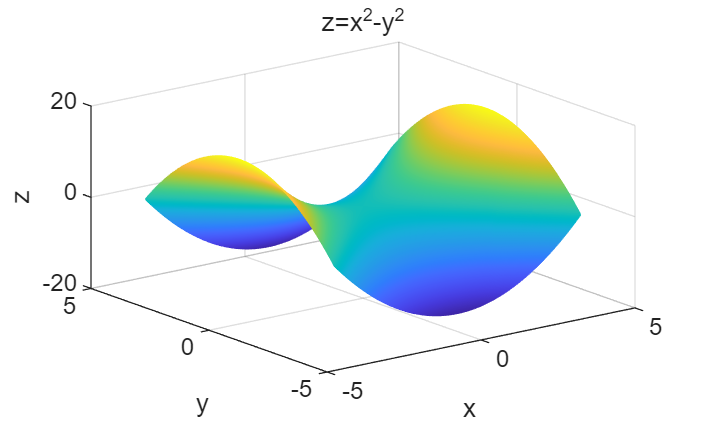

clear;
clc;

x=-4:0.01:4;
y=-4:0.01:4;
[X,Y]=meshgrid(x,y);

Z=(X.^2)-(Y.^2);

figure;
mesh(X, Y, Z);

title('z=x^2-y^2');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

8번 문제

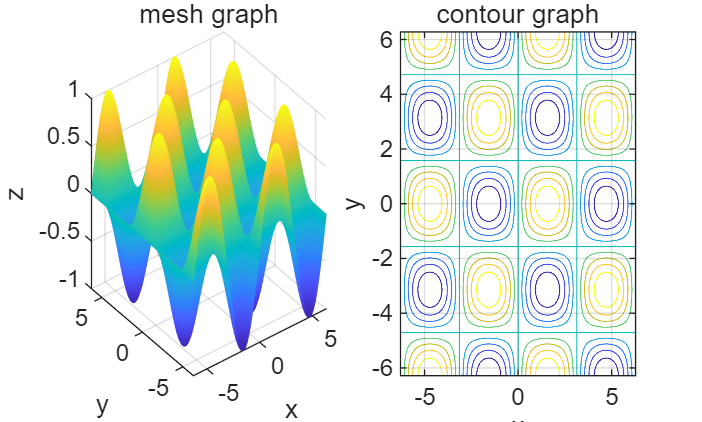

clear;
clc;

x=-2*pi:0.01:2*pi;
y=-2*pi:0.01:2*pi;

[X,Y]=meshgrid(x,y);

Z=sin(X).*cos(Y);
figure;

subplot(1,2,1);
mesh(X,Y,Z);
title('mesh graph');
xlabel('x');
ylabel('y');
zlabel('z');

subplot(1,2,2);
contour(X,Y,Z);
title('contour graph');
xlabel('x');
ylabel('y');
grid on;


%contour 그래프는 같은  z값을 연결 하여 함수의 높이 분포를 보여줌.

9번 문제

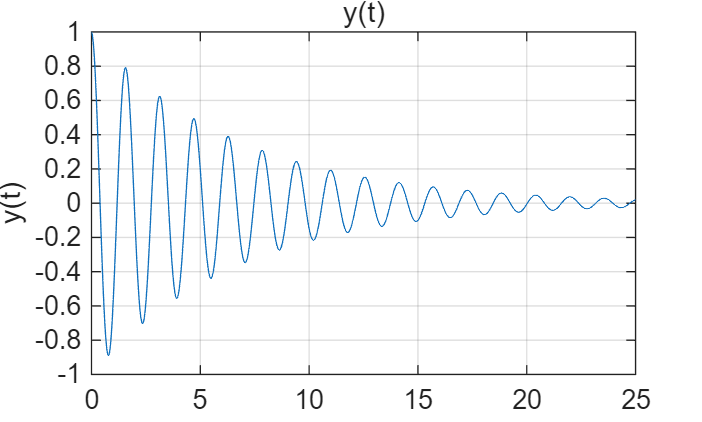

clear;
clc;

t=0:0.01:25;

y=exp(-0.15*t).*cos(4*t);

% a번 문제
figure;
plot(t,y);
title('y(t)');
xlabel('t');
ylabel('y(t)');
grid on;

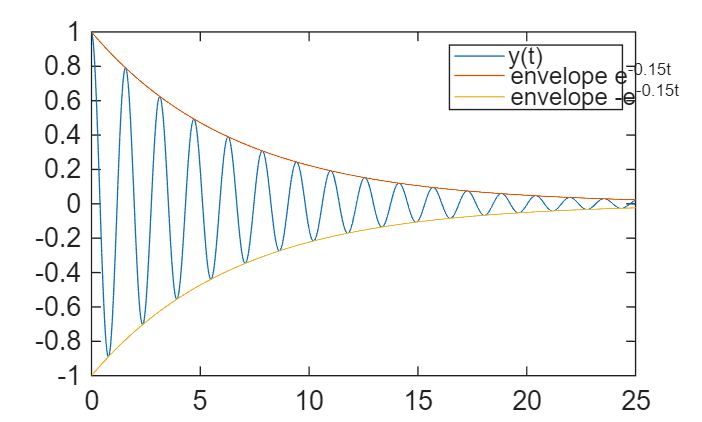


%b번 문제
figure;
plot(t,y);
hold on;
plot(t, exp(-0.15*t));
plot(t, -exp(-0.15*t));
legend('y(t)', 'envelope e^{-0.15t}', 'envelope -e^{-0.15t}');

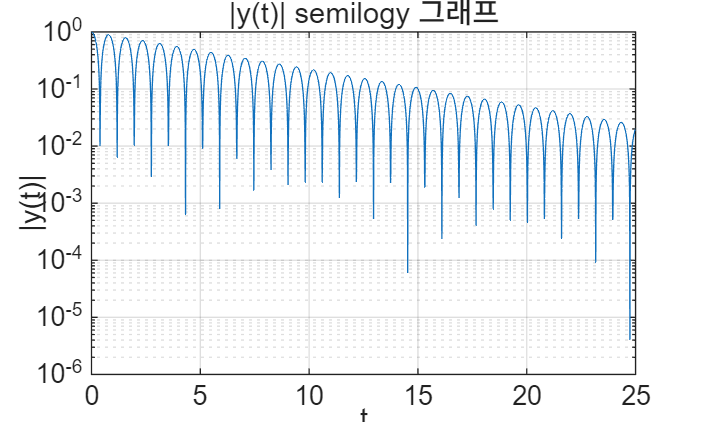


%c번 문제
figure;
semilogy(t, abs(y));
title('|y(t)| semilogy 그래프');
xlabel('t');
ylabel('|y(t)|');
grid on;


%로그 스케일에서는 지수 감쇠가 직선 형태로 나타나고 cos 함수에 의해 반복적인 요동도 생김.

10번 문제

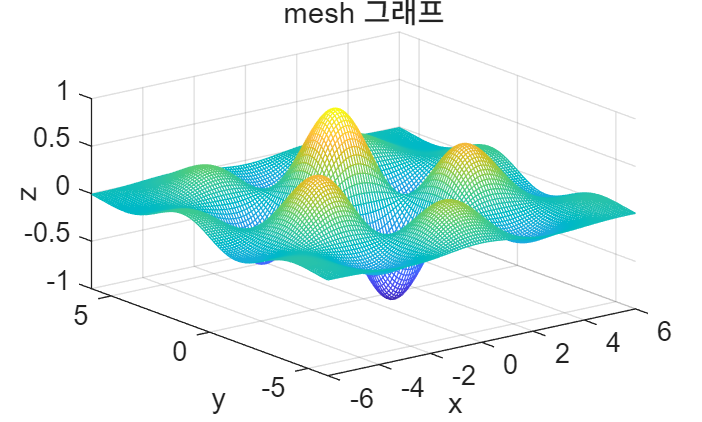

clear;
clc;

x=-6:0.1:6;
y=-6:0.1:6;

%a번 문제
[X,Y]=meshgrid(x,y);

Z=cos(X).*sin(Y).*exp(-0.05*(X.^2+Y.^2));

figure;

mesh(X,Y,Z);
title('mesh 그래프');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

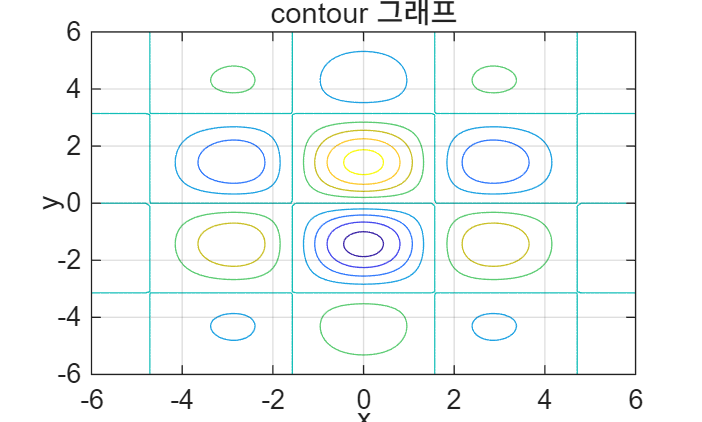


%b번 문제

figure;
contour(X,Y,Z);
title('contour 그래프');
xlabel('x');
ylabel('y');
grid on;


%c번 문제
[max_val, idx] = max(Z(:));

x_max = X(:);
y_max = Y(:);

x_max = x_max(idx);
y_max = y_max(idx);

disp(max_val);

    0.8935



disp(x_max);

     0



disp(y_max);

    1.4000



11번 문제

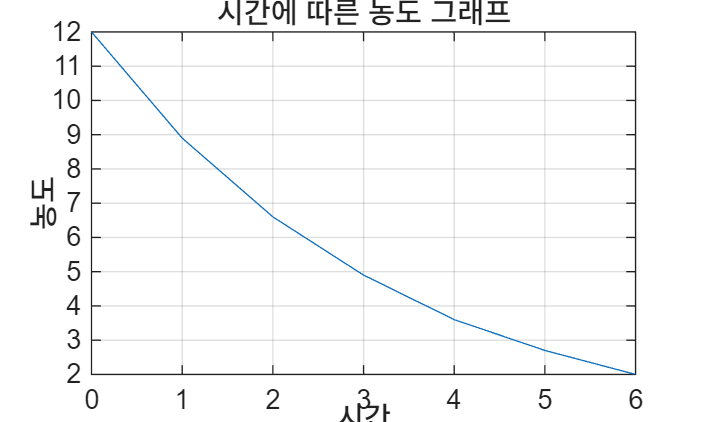

clear;
clc;

t=[0,1,2,3,4,5,6];
C=[12,8.9,6.6,4.9,3.6,2.7,2.0];

%a번 문제
figure;
plot(t,C);

title('시간에 따른 농도 그래프');
xlabel('시간');
ylabel('농도');
grid on;

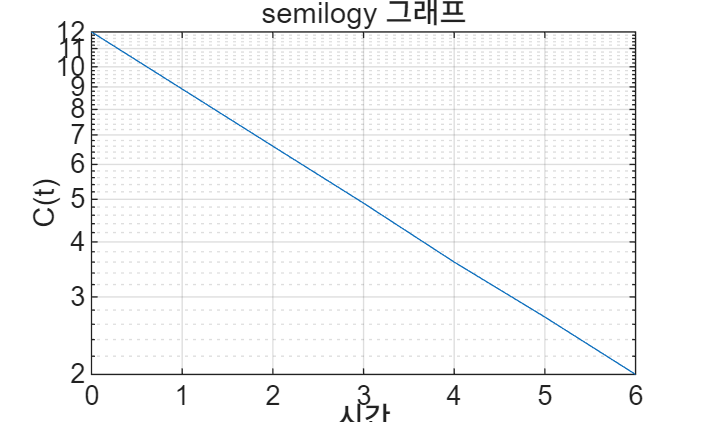


%b번 문제
figure;
semilogy(t,C);

title('semilogy 그래프');
xlabel('시간');
ylabel('C(t)');
grid on;


%c번 문제
logC=log(C);

k=-(logC(end)-logC(1))/(t(end)-t(1));

disp(k);

    0.2986



12번 문제

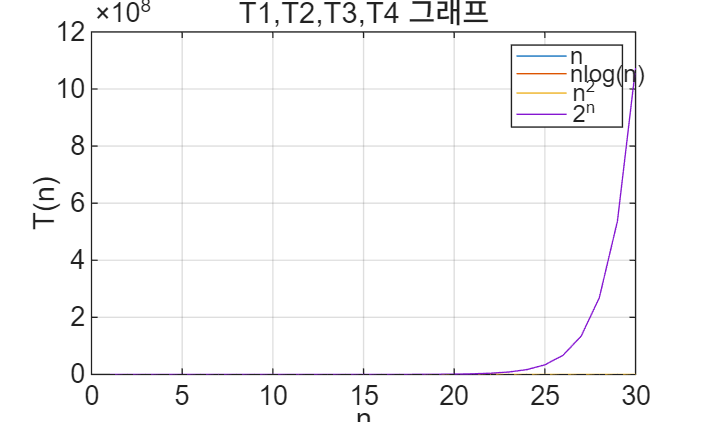

clear;
clc;

n=1:1:30;

T1=n;
T2=n.*log(n);
T3=n.^2;
T4=2.^n;

%a번 문제
figure;
plot(n,T1);
hold on;

plot(n,T2);
plot(n,T3);
plot(n,T4);

title('T1,T2,T3,T4 그래프');
xlabel('n');
ylabel('T(n)');
legend('n','nlog(n)','n^2','2^n');
grid on;

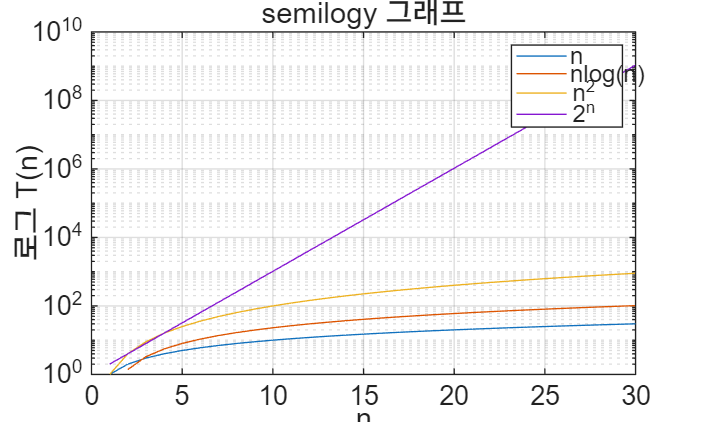


%b번 문제
figure;
semilogy(n,T1);
hold on;

semilogy(n,T2);
semilogy(n,T3);
semilogy(n,T4);

title('semilogy 그래프');
xlabel('n');
ylabel('로그 T(n)');
legend('n','nlog(n)','n^2','2^n');
grid on;


%c번 문제
%일반 그래프와 로그 스케일 그래프를 비교하였을 때 일반 그래프에서 2^n 값이 매우 빠르게 증가하므로 다른 값과 비교하기 힘들기
%때문에 로그 스케일 그래프가 성장률 비교에 더 적절함.

16번 문제

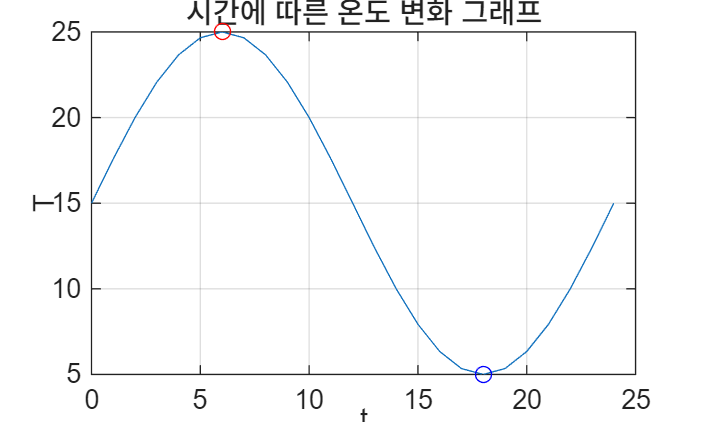

clear;
clc;

t=0:1:24;
T=15+10*sin(pi*t/12);

%1번 문제
figure;
plot(t,T);

title('시간에 따른 온도 변화 그래프');
xlabel('t');
ylabel('T');
grid on;

%2번 문제
[maxT, imax] = max(T);
[minT, imin] = min(T);

hold on;
plot(t(imax), maxT,'ro');
plot(t(imin), minT,'bo');


disp(maxT);

    25



disp(minT);

     5



17번 문제

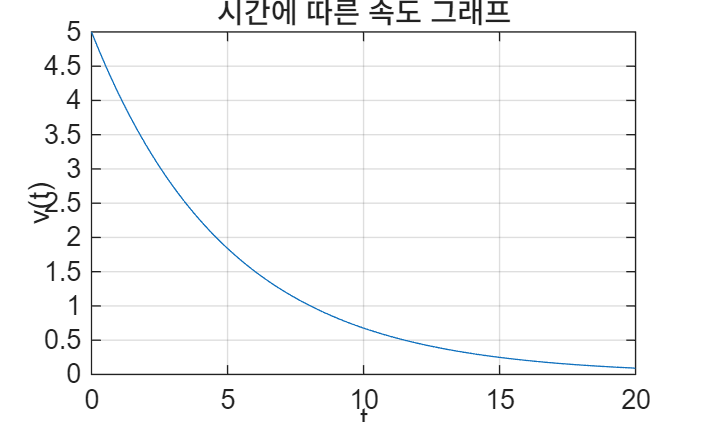

clear;
clc;

t=0:0.1:20;
v=5*exp(-0.2*t);

%1번 문제 
figure;
plot(t,v);

title('시간에 따른 속도 그래프');
xlabel('t');
ylabel('v(t)');
grid on;

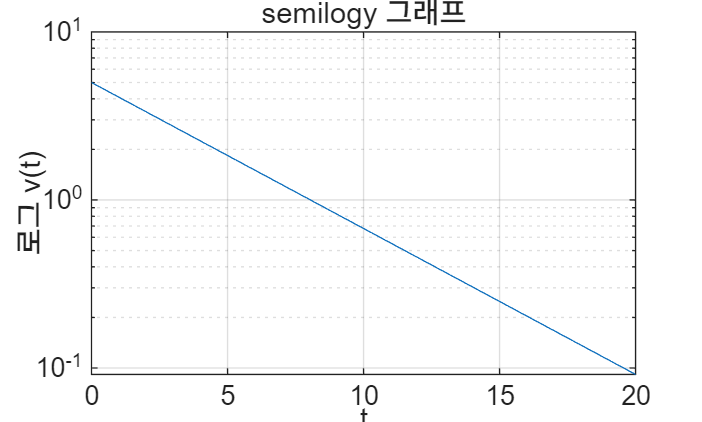


%2번 문제
figure;
semilogy(t,v);

title('semilogy 그래프');
xlabel('t');
ylabel('로그 v(t)');
grid on;


%3번 문제 
%일반 그래프에서는 감소하는 속도가 곡선 형태로 나타나고 semilogy 그래프에서는 감소하는 속도가 직선 형태로 나타남.

18번 문제 

clear;
clc;

A=[4 -1 2;1 3 -1;2 -2 5];
b=[7;4;10];

%a번 문제
A1=A^2;
A2=A.^2;

disp('A^2=');

A^2=


disp(A1);

    19   -11    19
     5    10    -6
    16   -18    31



disp('A.^2=');

A.^2=


disp(A2);

    16     1     4
     1     9     1
     4     4    25




%A^2는 행렬 곱셈으로 구한 행렬 값이고 A.^2는 각 원소를 각각 제곱한 행렬 값이므로 서로 다름.

%b번 문제
d=det(A);

disp('det(A)=');

det(A)=


disp(d);

    43




%행렬식이 0이 아니므로 역행렬이 존재함.

%c번 문제
C1=inv(A)*b;
C2=A\b;

disp('inv(A)*b=');

inv(A)*b=


disp(C1);

    1.0465
    1.7442
    2.2791



disp('A\b=');

A\b=


disp(C2);

    1.0465
    1.7442
    2.2791




%계산한 결과 둘 다 같은 값을 가짐.

%d번 문제
x=A\b;

disp('x=');

x=


disp(x);

    1.0465
    1.7442
    2.2791



19번 문제

clear;
clc;

A=[2 -1;3 4];
B=[1 0 -2;3 5 1];
C=[6 -3 4;15 14 -1];

%a번 문제
%AX+B=C;
%AX+B-B=C-B;
%AX=C-B;

%b번 문제
X=A\(C-B);

disp('X=');

X=


disp(X);

    2.9091   -0.2727    2.0000
    0.8182    2.4545   -2.0000




%c번 문제
left=A*X+B;
right=C;

disp('좌변 식:');

좌변 식:


disp(left);

    6.0000   -3.0000    4.0000
   15.0000   14.0000   -1.0000



disp('우변 식:')

우변 식:


disp(right);

     6    -3     4
    15    14    -1




%두 식이 같음

%d번 문제
%A\(C-B)은 inv(A)*(C-B)과 달리 역행렬을 사용하지 않고 답을 구하기 때문에 더 편리함.

20번 문제

clear;
clc;

X=[3 7 2 5;5 9 4 6;8 12 7 10;10 15 9 13;14 18 12 16];

%a번 문제
m=mean(X);

disp('각 열의 평균=');
disp(m);

%b번 문제 
Xc=X-m;

disp('중심화 행렬=');
disp(Xc);

%c번 문제 
S=Xc'*Xc;

disp('S=');
disp(S);

%d번 문제
%S의 대각 원소는 분산을 의미하고 비대각 원소는 공분산을 의미함.